clc;clear;


% 假设已知参数
theta1 = -45;     % 度
theta2 = 45;     % 度
sinPhiDiff = 0; % sin(phi1)-sin(phi2)
bcMinusA = 5;    % b+c-a 的值

[x, y] = locateReceiver(theta1, theta2, sinPhiDiff, bcMinusA);
fprintf('接收端坐标：(%f, %f)\n', x, y);

接收端坐标：(6.090000, -6.085000)


d1_1 = 2*sqrt(2.2^2+3.8^2) - (2*3.8)

d1_1 = 1.1818

d3_1 = 2 * 2.2 * sqrt(2) - 4.4

d3_1 = 1.8225

d3_2 = sqrt(2.2^2+3^2) * 2 - 6

d3_2 = 1.4404

tmp = 2.2 * sqrt(2) 

tmp = 3.1113

l1 = 2.2 / sqrt(3)

l1 = 1.2702


dis1 = sqrt((3.27-2.19)^2 + (2.39-1.27)^2)

dis1 = 1.5559


angle2 = rad2deg(atan(2.2/3))

angle2 = 36.2538

% 打开原文件和新文件
fid_in = fopen('.\Data\AODview45\AODr45_l0.log', 'r');
fid_out = fopen('.\Data\AODview45\AODr45_l0.txt', 'w');

% 循环读取每一行
while ~feof(fid_in)
    line = fgetl(fid_in);  % 读取一行
    % 判断并删除开头的 '00>'（含空格）
    if startsWith(line, '00> ')
        line = extractAfter(line, '00> ');
    elseif startsWith(line, '00>')
        line = extractAfter(line, '00>');
    end
    % 写入新文件
    fprintf(fid_out, '%s\n', line);
end

% 关闭文件
fclose(fid_in);
fclose(fid_out);

disp('处理完成！');

处理完成！


% 读取文本文件
% 迅速拿到lt3的数据然后跑起来
filename = '.\\Data\\data_for_doubleAOA_new\\plain1_30\\processed_rtt_files\\processed_test30_14.txt';  % <-- 改成你的文件名
fid = fopen(filename, 'r');
rawData = textscan(fid, '%s', 'Delimiter', '\n');
fclose(fid);
% 当前这个数据跑不了啊
% 获取行内容
lines = rawData{1};

% 初始化存储变量
rxenable_status = [];
frame_len = [];

pdoa_val = [];
degrees_val = [];
% CIR存储结构
Ipatov_CIR = [];
STS0_CIR = [];
STS1_CIR = [];

% 状态标志
current_mode = '';   % 当前是哪种CIR类型（Ipatov / STS0 / STS1）
inside_CIR_block = false;  % 是否正在读取CIR数据

% 遍历每一行，按规则提取
for i = 1:length(lines)
    line = strtrim(lines{i});
    
    % 解析 dwt_rxenable status
    if contains(line, 'dwt_rxenable status')
        tokens = regexp(line, 'dwt_rxenable status\s+0x([0-9A-Fa-f]+)', 'tokens');
        if ~isempty(tokens)
            rxenable_status = [rxenable_status, hex2dec(tokens{1}{1})];
        end
    end
    
   
    % 解析 Frame Received len
    if contains(line, 'Frame Received len')
        tokens = regexp(line, 'Frame Received len\s+(\d+)', 'tokens');
        if ~isempty(tokens)
            frame_len = [frame_len, str2double(tokens{1}{1})];
        end
    end
    
    % 解析 PDOA val 和 Degrees
    if contains(line, 'PDOA val')
        tokens = regexp(line, 'PDOA val\s*=\s*(\d+),\s*Degrees\s*=\s*([-+]?[0-9]*\.?[0-9]+)', 'tokens');
        if ~isempty(tokens)
            pdoa_val = [pdoa_val,str2double(tokens{1}{1})];
            degrees_val = [degrees_val,str2double(tokens{1}{2})];
        end
    end
    
 % 检测 CIR 类型标志
    if contains(line, 'Printing Ipatov CIR')
        current_mode = 'Ipatov';
        inside_CIR_block = false;  % 等待进入“-----------”段
    elseif contains(line, 'Printing STS0 CIR')
        current_mode = 'STS0';
        inside_CIR_block = false;  % 等待进入“-----------”段
    elseif contains(line, 'Printing STS1 CIR')
        current_mode = 'STS1';
        inside_CIR_block = false;  % 等待进入“-----------”段 
    end
    
    % 检测 “-----------” 的起始和结束
    if contains(line, '_________________________________')
        inside_CIR_block = ~inside_CIR_block;  % 切换状态
        continue;  % 这行不用处理
    end
    
    % 正在 CIR 数据块内，提取 I, Q
    if inside_CIR_block
        data_tokens = regexp(line, '(-?\d+),(-?\d+)', 'tokens');
        if ~isempty(data_tokens)
            I_val = str2double(data_tokens{1}{1});
            Q_val = str2double(data_tokens{1}{2});
            complex_val = I_val + 1j * Q_val;
            % 根据当前模式放入不同数组
            if strcmp(current_mode, 'Ipatov')
                Ipatov_CIR(end+1, 1) = complex_val;
            elseif strcmp(current_mode, 'STS0')
                STS0_CIR(end+1, 1) = complex_val;
            elseif strcmp(current_mode, 'STS1')
                STS1_CIR(end+1, 1) = complex_val;
            end
        end
    end
end

% 输出到命令行确认
disp(['dwt_rxenable status: ', num2str(rxenable_status)]);

dwt_rxenable status: 


disp(['Frame Received len: ', num2str(frame_len)]);

Frame Received len: 


 %packets_num = length(rxenable_status) ;
packets_num = length(STS0_CIR)/512;
%  Ipatov_CIR = reshape(Ipatov_CIR(1:1016 * packets_num), 1016, packets_num).';
% 共轭转置的问题
STS0_CIR = reshape(STS0_CIR(1:512 * packets_num), 512, packets_num).';
STS1_CIR = reshape(STS1_CIR(1:512 * packets_num), 512, packets_num).';

figure;
% Compute the magnitude of the CIR
Ipatov_magnitude = abs(Ipatov_CIR(1,:));

位置 1 处的索引超出数组边界。



% Plot the CIR in the complex plane (real vs imaginary)
figure(12);
plot(Ipatov_magnitude,'b');
title('Magnitude of CIR', 'FontSize', 16);
xlabel('Sample Index', 'FontSize', 14);
ylabel('Magnitude', 'FontSize', 14);
grid on;

% 

c =physconst("LightSpeed"); % wavelength (assume)
% lambda=c/4992.8e6;
lambda=c/7.9872e9;
antennaSpacing = lambda * 0.5;
% antennaSpacing = 0.0182;
% frequency=4992.8e6;
frequency=7.9872e9;
phase_offset = 0.17;
% -0.67, -0.88, -1.01， -0.72

pdoa_values_main = [];
degree_values_main = [];

pdoa_values_secondary = [];
degree_values_secondary = [];

peaks_index_STS0 = [];
peaks_index_STS1 = [];

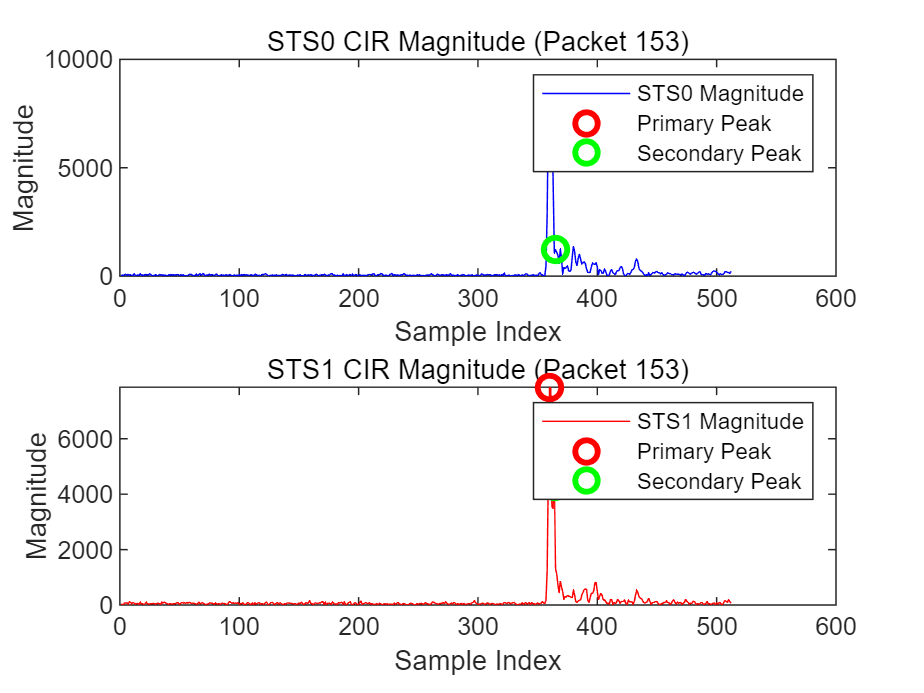

% 视频初始化
% video_filename = '.\Data\定位\Double_AOA_4_2_2.avi';
% v = VideoWriter(video_filename);  % 默认是 Motion JPEG AVI
% v.FrameRate = 5;  % 可根据需要调整帧率
% open(v);

% 初始化变量

for i = 1:packets_num
    % i =1 ;
    % 取出第 i 组 CIR 数据
    STS0_data = STS0_CIR(i,:);  
    STS1_data = STS1_CIR(i,:);
    
    % 幅度
    STS0_magnitude = abs(STS0_data);
    STS1_magnitude = abs(STS1_data);

    threshold = 0.1;  % 阈值

    min_peak_distance = 2;  % 峰值之间最少间隔 4 个采样点
    
    % 找峰值
    [peaks_STS0, locs_STS0] = findpeaks(STS0_magnitude, 'MinPeakHeight', threshold * max(STS0_magnitude), 'MinPeakDistance', min_peak_distance);
    [peaks_STS1, locs_STS1] = findpeaks(STS1_magnitude, 'MinPeakHeight', threshold * max(STS1_magnitude), 'MinPeakDistance', min_peak_distance);


    % 主峰和次强峰索引（需保证至少两个峰被找到）
    if length(locs_STS0) < 2 || length(locs_STS1) < 2
        continue; % 跳过不满足条件的帧
    end

    % 主峰和次强峰索引
    peak_index1_STS0 = locs_STS0(1);
    peak_index2_STS0 = locs_STS0(2);
    
    peak_index1_STS1 = locs_STS1(1);
    peak_index2_STS1 = locs_STS1(2);

%     if abs(peak_index1_STS1 - peak_index1_STS0) >=3 || abs(peak_index2_STS1 - peak_index2_STS0) >=3
%         continue;
%     end
    
    % 保存索引
    peaks_index_STS0 = [peaks_index_STS0; peak_index1_STS0, peak_index2_STS0];
    peaks_index_STS1 = [peaks_index_STS1; peak_index1_STS1, peak_index2_STS1];
    
    %% ---- 主峰相位差计算 ----
    STS0_phase_main = angle(STS0_data(peak_index1_STS0));
    STS1_phase_main = angle(STS1_data(peak_index1_STS1));
    phase_difference_main = STS1_phase_main - STS0_phase_main - phase_offset;
    phase_difference_main = mod(phase_difference_main + pi, 2*pi) - pi;

    theta_radians_main = asin(phase_difference_main * c / (2 * pi * antennaSpacing * frequency));
    theta_degrees_main = rad2deg(theta_radians_main);

    pdoa_values_main(1,end+1) = phase_difference_main;
    degree_values_main(1,end+1) = theta_degrees_main;
    
    %% ---- 次强峰相位差计算 ----
    STS0_phase_secondary = angle(STS0_data(peak_index2_STS0));
    STS1_phase_secondary = angle(STS1_data(peak_index2_STS1));
    phase_difference_secondary = STS1_phase_secondary - STS0_phase_secondary - phase_offset;
    phase_difference_secondary = mod(phase_difference_secondary + pi, 2*pi) - pi;

    theta_radians_secondary = asin(phase_difference_secondary * c / (2 * pi * antennaSpacing * frequency));
    theta_degrees_secondary = rad2deg(theta_radians_secondary);

    pdoa_values_secondary(1,end+1) = phase_difference_secondary;
    degree_values_secondary(1,end+1) = theta_degrees_secondary;

    %% ---- 画图并标记峰值 ----
    figure(100);
    clf; % 清空画布

    subplot(2,1,1);
    plot(STS0_magnitude, 'b');
    hold on;
    plot(peak_index1_STS0, STS0_magnitude(peak_index1_STS0), 'ro', 'MarkerSize', 8, 'LineWidth', 2); % 主峰
    plot(peak_index2_STS0, STS0_magnitude(peak_index2_STS0), 'go', 'MarkerSize', 8, 'LineWidth', 2); % 次强峰
    hold off;
    title(['STS0 CIR Magnitude (Packet ', num2str(i), ')']);
    xlabel('Sample Index');
    ylabel('Magnitude');
    legend('STS0 Magnitude', 'Primary Peak', 'Secondary Peak');

    subplot(2,1,2);
    plot(STS1_magnitude, 'r');
    hold on;
    plot(peak_index1_STS1, STS1_magnitude(peak_index1_STS1), 'ro', 'MarkerSize', 8, 'LineWidth', 2); % 主峰
    plot(peak_index2_STS1, STS1_magnitude(peak_index2_STS1), 'go', 'MarkerSize', 8, 'LineWidth', 2); % 次强峰
    hold off;
    title(['STS1 CIR Magnitude (Packet ', num2str(i), ')']);
    xlabel('Sample Index');
    ylabel('Magnitude');
    legend('STS1 Magnitude', 'Primary Peak', 'Secondary Peak');


    % % 把当前帧写入视频
    % frame = getframe(gcf);
    % writeVideo(v, frame);
end



% 关闭视频
% close(v);
% 
% disp(['视频已保存为: ', video_filename]);


peaks_index_diff = peaks_index_STS0 - peaks_index_STS1

peaks_index_diff =      0     2
     1     2
     1     2
     0     0
     0     2
     1     2
    -2    -1
     1     4
    -1    -1
     0     1


%这里在哪里有距离的计算？where is the distance?

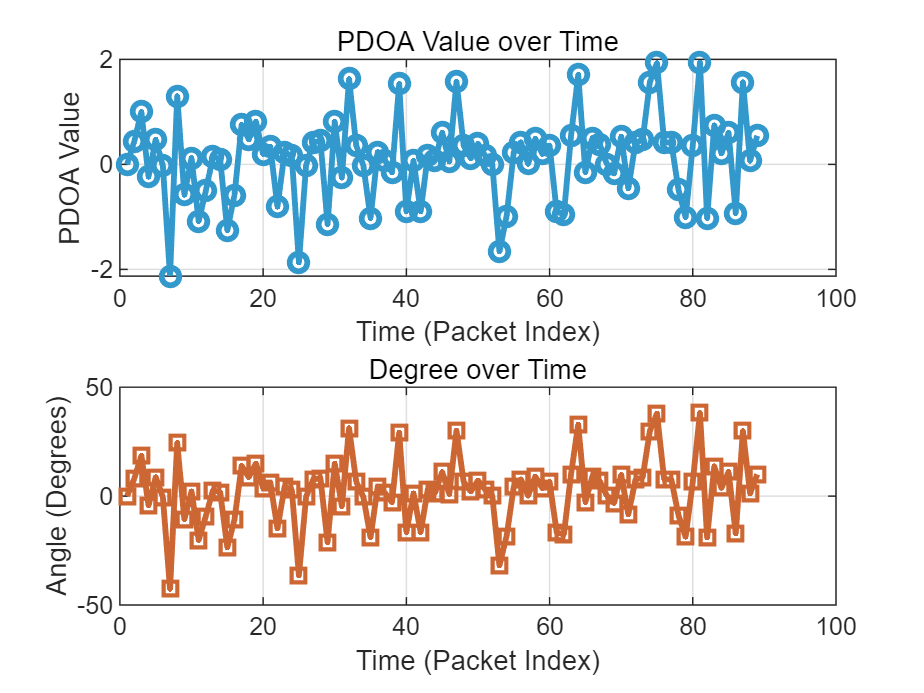

time = 1:length(pdoa_values_main);
figure;
subplot(2,1,1);
plot(time, pdoa_values_main, '-o', 'LineWidth', 2, 'Color', [0.2 0.6 0.8]);
title('PDOA Value over Time');
xlabel('Time (Packet Index)');
ylabel('PDOA Value');
grid on;

subplot(2,1,2);
plot(time, degree_values_main, '-s', 'LineWidth', 2, 'Color', [0.8 0.4 0.2]);
title('Degree over Time');
xlabel('Time (Packet Index)');
ylabel('Angle (Degrees)');
grid on;


% 1. 计算平均值
mean_pdoa = mean(pdoa_values_main);
mean_degree = mean(degree_values_main);

% 2. 计算标准差
std_pdoa = std(pdoa_values_main);
std_degree = std(degree_values_main);
% 显示结果
fprintf('PDOA 平均值: %.2f\n', mean_pdoa);

PDOA 平均值: 0.11


fprintf('PDOA 标准差: %.2f\n', std_pdoa);

PDOA 标准差: 0.81



fprintf('\nDegree 平均值: %.2f\n', mean_degree);


Degree 平均值: 2.12


fprintf('Degree 标准差: %.2f\n', std_degree);

Degree 标准差: 15.40


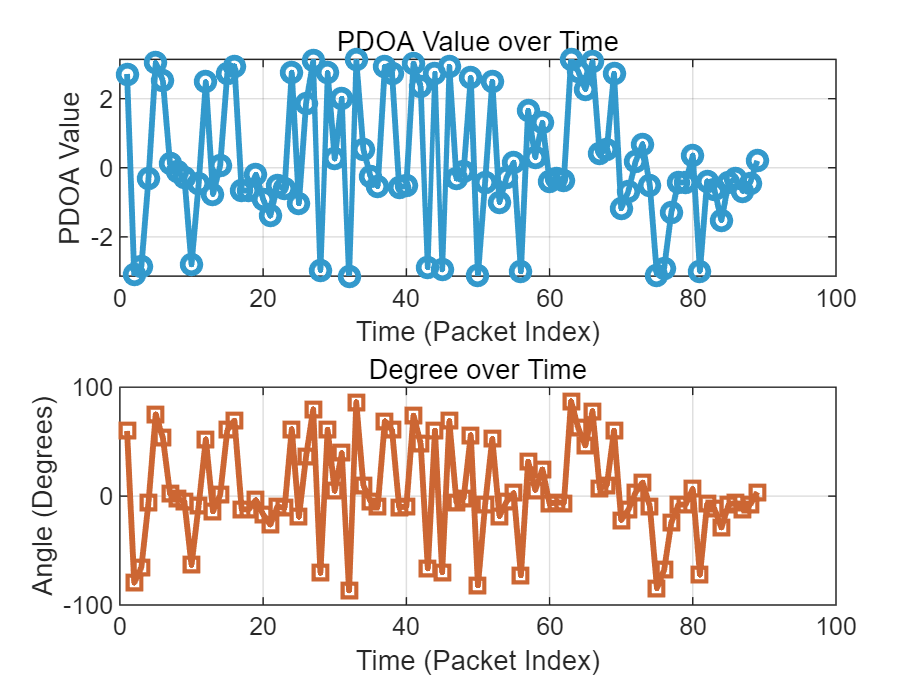

time = 1:length(pdoa_values_secondary);
figure;
subplot(2,1,1);
plot(time, pdoa_values_secondary, '-o', 'LineWidth', 2, 'Color', [0.2 0.6 0.8]);
title('PDOA Value over Time');
xlabel('Time (Packet Index)');
ylabel('PDOA Value');
grid on;

subplot(2,1,2);
plot(time, degree_values_secondary, '-s', 'LineWidth', 2, 'Color', [0.8 0.4 0.2]);
title('Degree over Time');
xlabel('Time (Packet Index)');
ylabel('Angle (Degrees)');
grid on;


% 1. 计算平均值
mean_pdoa = mean(pdoa_values_secondary);
mean_degree = mean(degree_values_secondary);

% 2. 计算标准差
std_pdoa = std(pdoa_values_secondary);
std_degree = std(degree_values_secondary);
% 显示结果
fprintf('PDOA 平均值: %.2f\n', mean_pdoa);

PDOA 平均值: 0.19


fprintf('PDOA 标准差: %.2f\n', std_pdoa);

PDOA 标准差: 1.89



fprintf('\nDegree 平均值: %.2f\n', mean_degree);


Degree 平均值: 4.52


fprintf('Degree 标准差: %.2f\n', std_degree);

Degree 标准差: 44.39



degree_values_dif = degree_values_main - degree_values_secondary

degree_values_dif =   -59.8424   87.6206   83.8555    1.1670  -66.4683  -53.9871  -44.7332   26.5049   -5.7484   65.4734  -11.7273  -61.4574   16.8273    0.7442  -84.3405  -80.2545   25.9692   20.8258   18.5470   20.3918   32.5685   -5.3366   15.1164  -58.5841  -17.3191  -36.7960  -72.2129   78.8461  -82.5487   10.2538  -44.3276  118.0751  -79.7783  -10.1059  -14.3144   14.1409  -67.3680  -63.5259   39.6720   -7.1234  -72.8234  -65.2689   69.8150  -58.9302   81.0475  -68.0494   35.9801    8.5494  -53.9958   89.3896


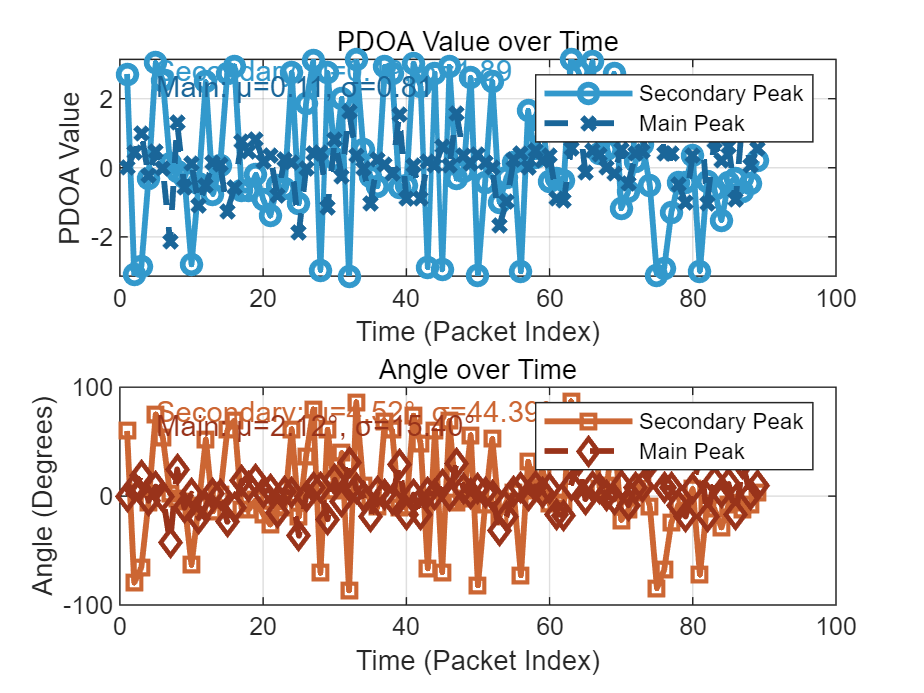

time = 1:length(pdoa_values_secondary);

figure;

%% =======================
% 次强峰 PDOA 曲线
subplot(2,1,1);
plot(time, pdoa_values_secondary, '-o', 'LineWidth', 2, 'Color', [0.2 0.6 0.8]); hold on;
plot(time, pdoa_values_main, '--x', 'LineWidth', 2, 'Color', [0.1 0.4 0.6]);
title('PDOA Value over Time');
xlabel('Time (Packet Index)');
ylabel('PDOA Value');
legend('Secondary Peak', 'Main Peak');
grid on;

% 添加均值 ± 标准差文本（次强）
mean_pdoa_sec = mean(pdoa_values_secondary);
std_pdoa_sec = std(pdoa_values_secondary);

mean_pdoa_main = mean(pdoa_values_main);
std_pdoa_main = std(pdoa_values_main);

text(5, max(pdoa_values_secondary)*0.9, sprintf('Secondary: μ=%.2f, σ=%.2f', mean_pdoa_sec, std_pdoa_sec), 'Color', [0.2 0.6 0.8], 'FontSize', 10);
text(5, max(pdoa_values_secondary)*0.75, sprintf('Main: μ=%.2f, σ=%.2f', mean_pdoa_main, std_pdoa_main), 'Color', [0.1 0.4 0.6], 'FontSize', 10);

%% =======================
% 次强峰 AOA 曲线
subplot(2,1,2);
plot(time, degree_values_secondary, '-s', 'LineWidth', 2, 'Color', [0.8 0.4 0.2]); hold on;
plot(time, degree_values_main, '--d', 'LineWidth', 2, 'Color', [0.6 0.2 0.1]);
title('Angle over Time');
xlabel('Time (Packet Index)');
ylabel('Angle (Degrees)');
legend('Secondary Peak', 'Main Peak');
grid on;

% 添加均值 ± 标准差文本（角度）
mean_degree_sec = mean(degree_values_secondary);
std_degree_sec = std(degree_values_secondary);

mean_degree_main = mean(degree_values_main);
std_degree_main = std(degree_values_main);

text(5, max(degree_values_secondary)*0.9, sprintf('Secondary: μ=%.2f°, σ=%.2f°', mean_degree_sec, std_degree_sec), 'Color', [0.8 0.4 0.2], 'FontSize', 10);
text(5, max(degree_values_secondary)*0.75, sprintf('Main: μ=%.2f°, σ=%.2f°', mean_degree_main, std_degree_main), 'Color', [0.6 0.2 0.1], 'FontSize', 10);


%% =======================
% 控制台输出所有结果
fprintf('—— PDOA ——\n');

—— PDOA ——


fprintf('Main Peak:\tMean = %.2f,\tStd = %.2f\n', mean_pdoa_main, std_pdoa_main);

Main Peak:	Mean = 0.11,	Std = 0.81


fprintf('Secondary:\tMean = %.2f,\tStd = %.2f\n\n', mean_pdoa_sec, std_pdoa_sec);

Secondary:	Mean = 0.19,	Std = 1.89




fprintf('—— AOA (Degree) ——\n');

—— AOA (Degree) ——


fprintf('Main Peak:\tMean = %.2f°,\tStd = %.2f°\n', mean_degree_main, std_degree_main);

Main Peak:	Mean = 2.12°,	Std = 15.40°


fprintf('Secondary:\tMean = %.2f°,\tStd = %.2f°\n', mean_degree_sec, std_degree_sec);

Secondary:	Mean = 4.52°,	Std = 44.39°


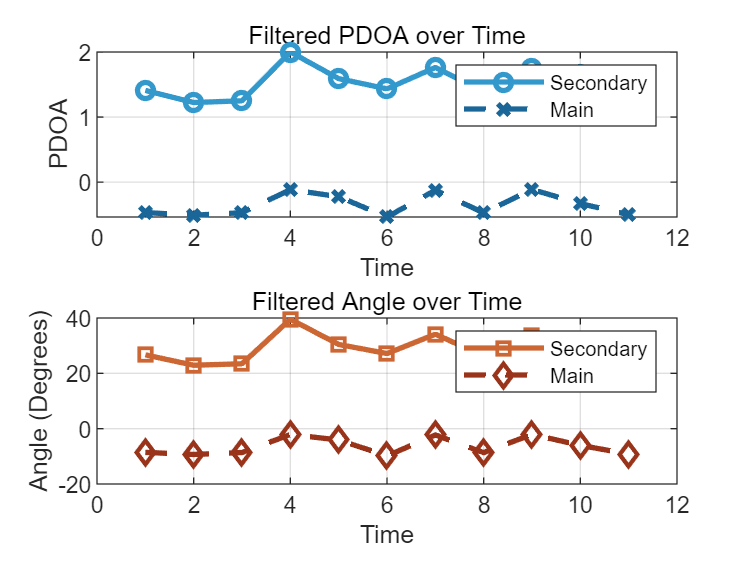

% 时间轴
time = 1:length(pdoa_values_secondary);

% 设置标准差倍数阈值
threshold = 2;

% 1. 计算均值与标准差
mean_pdoa_main = mean(pdoa_values_main);
std_pdoa_main  = std(pdoa_values_main);
mean_pdoa_sec  = mean(pdoa_values_secondary);
std_pdoa_sec   = std(pdoa_values_secondary);

mean_degree_main = mean(degree_values_main);
std_degree_main  = std(degree_values_main);
mean_degree_sec  = mean(degree_values_secondary);
std_degree_sec   = std(degree_values_secondary);

% 2. 生成逻辑索引（保留非异常值）
valid_main = abs(pdoa_values_main - mean_pdoa_main) <= threshold * std_pdoa_main & ...
             abs(degree_values_main - mean_degree_main) <= threshold * std_degree_main;

valid_sec = abs(pdoa_values_secondary - mean_pdoa_sec) <= threshold * std_pdoa_sec & ...
            abs(degree_values_secondary - mean_degree_sec) <= threshold * std_degree_sec;
% valid_main = abs(pdoa_values_main) <3
% valid_sec = abs(pdoa_values_secondary) <1

% 3. 应用过滤（注意时间轴也要同步筛选）
filtered_time_main = time(valid_main);
filtered_pdoa_main = pdoa_values_main(valid_main);
filtered_degree_main = degree_values_main(valid_main);

filtered_time_sec = time(valid_sec);
filtered_pdoa_sec = pdoa_values_secondary(valid_sec);
filtered_degree_sec = degree_values_secondary(valid_sec);

% 4. 重新计算滤除后的统计量
mu_p_main = mean(filtered_pdoa_main);  sigma_p_main = std(filtered_pdoa_main);
mu_d_main = mean(filtered_degree_main);sigma_d_main = std(filtered_degree_main);

mu_p_sec = mean(filtered_pdoa_sec);    sigma_p_sec = std(filtered_pdoa_sec);
mu_d_sec = mean(filtered_degree_sec);  sigma_d_sec = std(filtered_degree_sec);

% 5. 绘图
figure;
subplot(2,1,1);
plot(filtered_time_sec, filtered_pdoa_sec, '-o', 'LineWidth', 2, 'Color', [0.2 0.6 0.8]); hold on;
plot(filtered_time_main, filtered_pdoa_main, '--x', 'LineWidth', 2, 'Color', [0.1 0.4 0.6]);
title('Filtered PDOA over Time');
xlabel('Time'); ylabel('PDOA'); legend('Secondary', 'Main'); grid on;

subplot(2,1,2);
plot(filtered_time_sec, filtered_degree_sec, '-s', 'LineWidth', 2, 'Color', [0.8 0.4 0.2]); hold on;
plot(filtered_time_main, filtered_degree_main, '--d', 'LineWidth', 2, 'Color', [0.6 0.2 0.1]);
title('Filtered Angle over Time');
xlabel('Time'); ylabel('Angle (Degrees)'); legend('Secondary', 'Main'); grid on;


% 6. 控制台输出
fprintf('【滤除异常值后的结果】\n');

【滤除异常值后的结果】


fprintf('—— PDOA ——\n');

—— PDOA ——


fprintf('Main Peak:\tMean = %.2f,\tStd = %.2f\n', mu_p_main, sigma_p_main);

Main Peak:	Mean = -0.35,	Std = 0.17


fprintf('Secondary:\tMean = %.2f,\tStd = %.2f\n', mu_p_sec, sigma_p_sec);

Secondary:	Mean = 1.52,	Std = 0.25



fprintf('—— AOA (Degree) ——\n');

—— AOA (Degree) ——


fprintf('Main Peak:\tMean = %.2f°,\tStd = %.2f°\n', mu_d_main, sigma_d_main);

Main Peak:	Mean = -6.43°,	Std = 3.20°


fprintf('Secondary:\tMean = %.2f°,\tStd = %.2f°\n', mu_d_sec, sigma_d_sec);

Secondary:	Mean = 29.04°,	Std = 5.38°


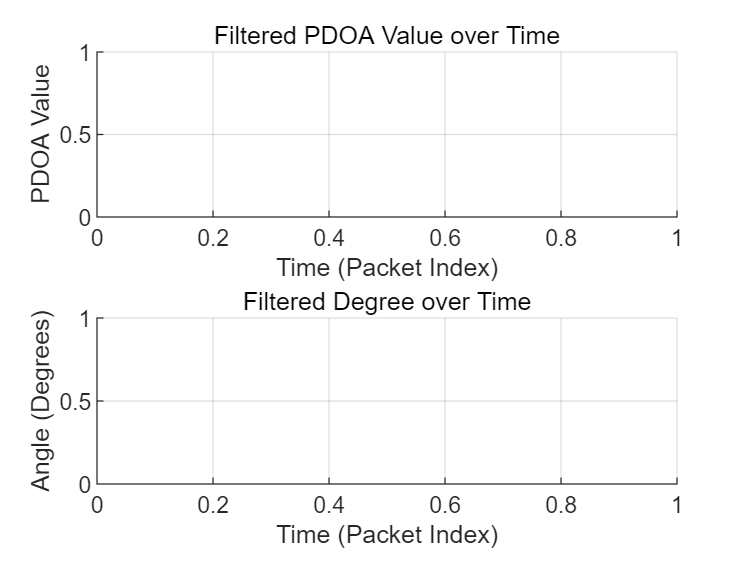

% 原始时间向量
time = 1:length(pdoa_values_main);

% 使用已有的均值和标准差
% mean_pdoa, std_pdoa
    % mean_degree, std_degree

% 设置过滤阈值（通常为2或3倍标准差）
threshold = 2;

% 筛选非异常值的逻辑索引
valid_idx = abs(pdoa_values_main - mean_pdoa) <= threshold * std_pdoa & ...
            abs(degree_values_main - mean_degree) <= threshold * std_degree;

% 应用筛选条件
filtered_pdoa = pdoa_values_main(valid_idx);
filtered_degree = degree_values_main(valid_idx);
filtered_time = time(valid_idx);

% 绘图：滤除异常值后的数据
figure;
subplot(2,1,1);
plot(filtered_time, filtered_pdoa, '-o', 'LineWidth', 2, 'Color', [0.2 0.6 0.8]);
title('Filtered PDOA Value over Time');
xlabel('Time (Packet Index)');
ylabel('PDOA Value');
grid on;

subplot(2,1,2);
plot(filtered_time, filtered_degree, '-s', 'LineWidth', 2, 'Color', [0.8 0.4 0.2]);
title('Filtered Degree over Time');
xlabel('Time (Packet Index)');
ylabel('Angle (Degrees)');
grid on;


% 再次计算滤波后数据的统计量
mean_filtered_pdoa = mean(filtered_pdoa);
std_filtered_pdoa = std(filtered_pdoa);
mean_filtered_degree = mean(filtered_degree);
std_filtered_degree = std(filtered_degree);

% 输出滤除异常值后的结果
fprintf('【滤除异常值后的结果】\n');

【滤除异常值后的结果】


fprintf('PDOA 平均值: %.2f\n', mean_filtered_pdoa);

PDOA 平均值: NaN


fprintf('PDOA 标准差: %.2f\n', std_filtered_pdoa);

PDOA 标准差: NaN



fprintf('\nDegree 平均值: %.2f\n', mean_filtered_degree);


Degree 平均值: NaN


fprintf('Degree 标准差: %.2f\n', std_filtered_degree);

Degree 标准差: NaN


AOA = -15;
AOA = deg2rad(AOA);
PDOA_GT = antennaSpacing * sin(AOA) * (2 * pi) / lambda

PDOA_GT = -0.8131

reflection_angel = rad2deg(atan(1.6/2.4))

% function x0 = findLocalization(theta1, theta2, phi1, phi2, rTOF)
%     theta1 = deg2rad(theta1);
%     theta2 = deg2rad(theta2);
%     phi1 = deg2rad(phi1);
%     phi2 = deg2rad(phi2);
% 
%     % 定义网格大小和范围
%     gridRange = 20;
%     gridSize = 0.5;
% 
%     % 生成网格点坐标
%     [x1, y1, x2, y2] = ndgrid(-gridRange:gridSize:gridRange, -gridRange:gridSize:gridRange, -gridRange:gridSize:gridRange, -gridRange:gridSize:gridRange);
%     x0_all = [x1(:), y1(:), x2(:), y2(:)];
% 
%     % 计算目标函数值
%     objectiveValues = objectiveFunction(x0_all, theta1, theta2, phi1, phi2, rTOF);
% 
%     % 找到目标函数值最小的前10个候选解
%     [~, sortedIdx] = mink(objectiveValues, 10);  % 或 sort(objectiveValues)
%     x0 = x0_all(sortedIdx, :);
% end
% 
% function fval = objectiveFunction(x, theta1, theta2, phi1, phi2, rTOF)
%     x1 = x(:, 1);
%     y1 = x(:, 2);
%     x2 = x(:, 3);
%     y2 = x(:, 4);
% 
%     % 计算目标函数值
%     fval = (tan(theta1) - x1./y1).^2 + (tan(theta2) - x2./y2).^2 + (tan(phi1 + theta1 - phi2) - (x1 - x2)./(y1 - y2)).^2 + ((rTOF * physconst('Lightspeed') * 1e-9) - (-sqrt(x1.^2 + y1.^2) + sqrt(x2.^2 + y2.^2) + sqrt((x1 - x2).^2 + (y1 - y2).^2))).^2;
% end
% 
% function xOpt = optimizeLocalization(x0, theta1, theta2, phi1, phi2, rTOF)
%     % 转换角度为弧度
%     theta1 = deg2rad(theta1);
%     theta2 = deg2rad(theta2);
%     phi1 = deg2rad(phi1);
%     phi2 = deg2rad(phi2);
% 
%     % 迭代搜索参数
%     searchParams = {
%         struct('range', 1, 'step', 0.03) % 中等搜索范围和步长
%     };
% 
%     % 逐级迭代搜索
%     for i = 1:length(searchParams)
%         param = searchParams{i};
%         fineRange = param.range;
%         fineStep = param.step;
% 
%         % 动态生成精细的网格点坐标
%         x1Range = (x0(1)-fineRange):fineStep:(x0(1)+fineRange);
%         y1Range = (x0(2)-fineRange):fineStep:(x0(2)+fineRange);
%         x2Range = (x0(3)-fineRange):fineStep:(x0(3)+fineRange);
%         y2Range = (x0(4)-fineRange):fineStep:(x0(4)+fineRange);
% 
%         [X1, Y1, X2, Y2] = ndgrid(x1Range, y1Range, x2Range, y2Range);
%         fineGrid = [X1(:), Y1(:), X2(:), Y2(:)];
% 
%         % 计算目标函数值
%         fineObjectiveValues = objectiveFunction(fineGrid, theta1, theta2, phi1, phi2, rTOF);
% 
%         % 找到最小值
%         [~, fineIdx] = min(fineObjectiveValues);
%         x0 = fineGrid(fineIdx, :);
%         % disp(['Iteration ', num2str(i), ' Best x0: ', mat2str(x0)]);
%     end
% 
%     xOpt = x0;
% end
% 


% 接收端法线右侧正方向，发射端法线左侧正方向
theta1 = -45;
phi1 = 0;
theta2 = -45;
phi2 = 0;
tdoa =  1.9882/ 0.3;

% 获取前10个候选点，每行是[x1, y1, x2, y2]
x0 = findLocalization(theta1, phi1, theta2, phi2, tdoa);

x0(1,:) = -x0(1,:); % 翻转x轴
x0(2,:) = -x0(2,:); % 翻转y轴
% 定义旋转角度和旋转矩阵（顺时针旋转50度）
theta = deg2rad(-45);  
R = [cos(theta), sin(theta); -sin(theta), cos(theta)];

% 对每个点的(x1, y1)部分进行旋转
rotated_xy1 = (R * x0(:, 1:2)')';  % 10×2 结果
% 如果你还想对 (x2, y2) 部分也旋转，加下面这行：
rotated_xy2 = (R * x0(:, 3:4)')';  % 10×2 结果

% 拼接旋转后的结果（如果需要）
rotated_x0 = [rotated_xy1, rotated_xy2];

% 显示结果
disp(rotated_x0);

% x0=optimizeLocalization(x0,theta1,phi1,theta2,phi2,tdoa);


% 将x0整理成2行2列
x0 = reshape(x0, 2, 2);

% 翻转坐标（根据需要修正方向）
x0(1,:) = -x0(1,:); % 翻转x轴
x0(2,:) = -x0(2,:); % 翻转y轴

% 定义旋转矩阵（顺时针45度）
theta = deg2rad(-50);
R = [cos(theta), sin(theta); -sin(theta), cos(theta)];

% 旋转每个点
rotated_vector = R * x0; 


% 显示最终结果
disp('定位结果（第一列是标签，第二列是反射物）：');
disp(rotated_vector);

clc;
clear;
close all;

 % % 绘制信号
    % figure;
    % plot(STS0_magnitude,'k', 'LineWidth', 3);  % 黑色线条，可根据需要修改颜色
    % axis off                          % 关闭坐标轴
    % set(gca, 'Color', 'none');        % 坐标区背景也设为透明
    % 
    % % 调整边距
    % set(gca, 'position', [0 0 1 1]);  % 图像占满整个画布
    % set(gcf, 'Units', 'pixels', 'Position', [100 100 800 200]);  % 可设置图像分辨率大小
    % 
    % % 保存为透明背景图像（推荐PNG格式）
    % exportgraphics(gca, 'STS0.png', 'BackgroundColor', 'none', 'Resolution', 300);

%探究相对飞行时间的准确性 
interval1 = peaks_index_STS1(:,2) - peaks_index_STS1(:,1);
error1 = interval1 * c * 1e-9 - 2.5231;

interval2 = peaks_index_STS0(:,2) - peaks_index_STS0(:,1);
error2 = interval2 * c * 1e-9 - 2.5231;

error = [error1;error2]

% 添加微小扰动（标准差为1e-4米）
jitter = 15 * randn(size(error)) * 1e-2;  % 正态分布扰动
error_jittered = error + jitter;

% 绘制误差CDF图
figure;
cdfplot(abs(error_jittered));  % 绘制CDF
xlabel('相对飞行距离误差 (m)');
ylabel('CDF');
title('');
grid on;
hold on;

% 计算中位误差
median_error = median(abs(error_jittered));



% 为手动绘制中位误差点的横线与竖线做准备
% 计算CDF数据（以便获取纵坐标）
[sorted_errors, sort_idx] = sort(abs(error_jittered));
cdf = (1:length(sorted_errors))' / length(sorted_errors);

% 找到最接近中位误差的位置
[~, idx_median] = min(abs(sorted_errors - median_error));
x_median = sorted_errors(idx_median);
y_median = cdf(idx_median);

% 绘制从坐标轴到中位误差点的辅助虚线
plot([x_median, x_median], [0, y_median], 'r--', 'LineWidth', 1.2);  % 竖线
plot([0, x_median], [y_median, y_median], 'r--', 'LineWidth', 1.2);  % 横线

% 标注中位误差点
plot(x_median, y_median, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
text(x_median + 0.02, y_median + 0.02, ...
    sprintf('中位误差 = %.3f m', x_median), ...
    'Color', 'r', 'FontSize', 10);

% 保持图像风格一致
box on;

% 探究不同环境
%=========================% 
% 真实参数（无噪声）讨论间
true_theta1 = 45;    % AoA 1
true_theta2 = 4.9;   % AoA 2 
true_phi1   = 45;    % AoD 1 
true_phi2   = 4.9;   % A0D 2 
true_rTOF   = 6;     % 飞行时间（ns） 
orientation = 45;    %接收天线朝向
true_tag_pos = [3.2 ; 0]; % 第一列是标签位置 

% true_theta1 = 45;    % 发射端角度 
% true_theta2 = -5;   % 接收端角度 
% true_phi1   = 45;    % 法线夹角 
% true_phi2   = -5;   % 法线夹角 
% true_rTOF   = 12;     % 飞行时间（ns）
% orientation = 45;    %接收天线朝向

true_tag_pos = findLocalization(true_theta1,true_theta2,true_phi1,true_phi2,true_rTOF);
true_tag_pos = optimizeLocalization(true_tag_pos, true_theta1,true_theta2,true_phi1,true_phi2,true_rTOF);
true_tag_pos = reshape(true_tag_pos, 2, 2); 
true_tag_pos(1,:) = -true_tag_pos(1,:); 
true_tag_pos(2,:) = -true_tag_pos(2,:); 

theta = deg2rad(45); 
R = [cos(theta), sin(theta); -sin(theta), cos(theta)]; 
true_tag_pos = R * true_tag_pos; 

% true_tag_pos = true_tag_pos(:,1); % 第一列是标签位置 


%=========================% 
% 模拟误差大小 
angle_error_deg = 0;    % 角度误差 ±5度 
distance_error_m = 0; % 距离误差 ±0.3米 

%=========================% 
% 仿真次数（为了稳健，可以多次仿真） 
num_trials = 1; 

%=========================% 
% 记录误差 
position_errors = zeros(num_trials, 1); 

% 记录超过1m误差时的角度和距离
error_angles_distances = [];

for trial = 1:num_trials

    noisy_theta1 = true_theta1 + (rand * 2 * angle_error_deg - angle_error_deg); 
    noisy_theta2 = true_theta2 + (rand * 2 * angle_error_deg - angle_error_deg); 
    noisy_phi1   = true_phi1   + (rand * 2 * angle_error_deg - angle_error_deg); 
    noisy_phi2   = true_phi2   + (rand * 2 * angle_error_deg - angle_error_deg); 

    lightspeed = physconst('Lightspeed'); % m/s 
    true_distance = true_rTOF * lightspeed * 1e-9; % ns -> m 
    noisy_distance = true_distance + (rand * 2 * distance_error_m - distance_error_m); % 加测量误差 
    noisy_rTOF = noisy_distance / lightspeed / 1e-9; % 再换回ns 

    x0 = findLocalization(noisy_theta1, noisy_theta2, noisy_phi1, noisy_phi2, noisy_rTOF); 
    x0 = optimizeLocalization(x0, noisy_theta1, noisy_theta2, noisy_phi1, noisy_phi2, noisy_rTOF); 

    x0 = reshape(x0, 2, 2); 
    x0(1,:) = -x0(1,:); 
    x0(2,:) = -x0(2,:); 

    theta = deg2rad(45); 
    R = [cos(theta), sin(theta); -sin(theta), cos(theta)]; 
    rotated_vector = R * x0; 

    estimated_tag_pos = rotated_vector(:,1); % 第一列是标签位置 

    error_val = norm(estimated_tag_pos - true_tag_pos); 
    position_errors(trial) = error_val;

    if error_val > 1
        error_angles_distances = [error_angles_distances; ...
            trial, noisy_theta1, noisy_theta2, noisy_phi1, noisy_phi2, noisy_distance];
    end

end

% 显示结果
disp('误差超过1米的情况：');
disp('Trial   theta1   theta2   phi1   phi2   distance(m)');
disp(error_angles_distances);



mean_error = mean(position_errors);
std_error = std(position_errors);

fprintf('模拟次数: %d 次\n', num_trials);
fprintf('角度误差: ±%.1f°，距离误差: ±%.2f m\n', angle_error_deg, distance_error_m);
fprintf('平均定位误差: %.4f m\n', mean_error);
fprintf('定位误差标准差: %.4f m\n', std_error);


figure;
histogram(position_errors, 'BinWidth', 0.05);
xlabel('定位误差 (米)');
ylabel('次数');
title(sprintf('角度误差±%.1f° + 距离误差±%.2fm\n平均误差 %.3fm', angle_error_deg, distance_error_m, mean_error));
grid on;

% 绘制CDF图并标出中位误差位置
figure;
sorted_errors = sort(position_errors);
cdf = (1:num_trials) / num_trials;
plot(sorted_errors, cdf, 'LineWidth', 2);
hold on;

% 计算中位误差
median_error = median(position_errors);

% 找到中位误差对应的纵坐标 (大约是0.5) 和最近的点
[~, idx_median] = min(abs(sorted_errors - median_error));
x_median = sorted_errors(idx_median);
y_median = cdf(idx_median);

% 手动画短横线和竖线（仅到点为止）
plot([x_median, x_median], [0, y_median], '--r', 'LineWidth', 1.5); % 竖线
plot([0, x_median], [y_median, y_median], '--r', 'LineWidth', 1.5); % 横线

% 添加标注
text(x_median + 0.02, y_median + 0.02, sprintf('中位误差 = %.3f m', x_median), 'Color', 'r');

xlabel('定位误差 (米)');
ylabel('CDF');
grid on;

% 探究距离影响

%=========================% 
% 固定参数：角度与误差
true_theta1 = 45;
true_theta2 = -23;
true_phi1   = 45;
true_phi2   = -23;
orientation = 45;

angle_error_deg = 4;        % 角度误差 ±6度
distance_error_m = 0.3;    % 距离误差 ±0.35m
num_trials = 10;           % 每个距离的仿真次数

%=========================% 
% 距离设置（单位：米）
distances_m = 1:1:10;       % 1米到10米，每步1米
num_distances = length(distances_m);

% 结果记录
mean_errors = zeros(num_distances, 1);
std_errors = zeros(num_distances, 1);

for d_idx = 1:num_distances
    true_distance = distances_m(d_idx);
    true_rTOF = true_distance / physconst('Lightspeed') / 1e-9; % ns

    true_tag_pos = findLocalization(true_theta1,true_theta2,true_phi1,true_phi2,true_rTOF);
    true_tag_pos = optimizeLocalization(true_tag_pos, true_theta1,true_theta2,true_phi1,true_phi2,true_rTOF);
    true_tag_pos = reshape(true_tag_pos, 2, 2); 
    true_tag_pos(1,:) = -true_tag_pos(1,:); 
    true_tag_pos(2,:) = -true_tag_pos(2,:); 

    theta = deg2rad(orientation); 
    R = [cos(theta), sin(theta); -sin(theta), cos(theta)]; 
    true_tag_pos = R * true_tag_pos; 
    true_tag_pos = true_tag_pos(:,1); 

    position_errors = zeros(num_trials, 1); 

    for trial = 1:num_trials
        noisy_theta1 = true_theta1 + (rand * 2 * angle_error_deg - angle_error_deg); 
        noisy_theta2 = true_theta2 + (rand * 2 * angle_error_deg - angle_error_deg); 
        noisy_phi1   = true_phi1   + (rand * 2 * angle_error_deg - angle_error_deg); 
        noisy_phi2   = true_phi2   + (rand * 2 * angle_error_deg - angle_error_deg); 

        noisy_distance = true_distance + (rand * 2 * distance_error_m - distance_error_m); 
        noisy_rTOF = noisy_distance / physconst('Lightspeed') / 1e-9; 

        x0 = findLocalization(noisy_theta1, noisy_theta2, noisy_phi1, noisy_phi2, noisy_rTOF); 
        x0 = optimizeLocalization(x0, noisy_theta1, noisy_theta2, noisy_phi1, noisy_phi2, noisy_rTOF); 

        x0 = reshape(x0, 2, 2); 
        x0(1,:) = -x0(1,:); 
        x0(2,:) = -x0(2,:); 
        rotated_vector = R * x0; 
        estimated_tag_pos = rotated_vector(:,1); 

        error_val = norm(estimated_tag_pos - true_tag_pos); 
        position_errors(trial) = error_val;
    end

    mean_errors(d_idx) = mean(position_errors);
    std_errors(d_idx) = std(position_errors);
end

%=========================% 
% 绘图：平均误差和标准差随距离变化
figure;
errorbar(distances_m, mean_errors, std_errors, 'o-', 'LineWidth', 2);
xlabel('真实距离 (米)');
ylabel('定位误差 (米)');
grid on;
legend('平均误差 ±1σ');


% 探究发包数量对定位结果的影响
%=========================% 
% ==================== 固定参数 ====================
true_theta1 = 45;
true_theta2 = -23;
true_phi1   = 45;
true_phi2   = -23;
orientation = 45;
true_rTOF = 12; % ns
lightspeed = physconst('Lightspeed'); % m/s 
true_distance = true_rTOF * lightspeed * 1e-9; % ns -> m 
true_tag_pos = findLocalization(true_theta1,true_theta2,true_phi1,true_phi2,true_rTOF);
true_tag_pos = optimizeLocalization(true_tag_pos, true_theta1,true_theta2,true_phi1,true_phi2,true_rTOF);
true_tag_pos = reshape(true_tag_pos, 2, 2);
true_tag_pos(1,:) = -true_tag_pos(1,:);
true_tag_pos(2,:) = -true_tag_pos(2,:);
R = [cosd(orientation), sind(orientation); -sind(orientation), cosd(orientation)];
true_tag_pos = R * true_tag_pos;
true_tag_pos = true_tag_pos(:,1);


angle_error_deg = 5;         % 角度误差 ±5度
distance_error_m = 0.3;      % 距离误差 ±0.3m

% ==================== 发包设置 ====================
trial_counts = [5, 10, 20, 50];           % 每组发包数
fixed_trial_number = 50;               % 每种发包设置的重复次数
num_trial_settings = length(trial_counts);
errors_all_trials = cell(1, num_trial_settings);  % 每种设置下误差集

% ==================== 主循环 ====================
for t_idx = 1:num_trial_settings
    num_packets = trial_counts(t_idx);                     % 每组发包次数
    averaged_errors = zeros(fixed_trial_number, 1);        % 每组取平均的误差

    for group = 1:fixed_trial_number
        error_per_group = zeros(num_packets, 1);           % 单组内多个误差

        for pkt = 1:num_packets
            % 添加噪声
            noisy_theta1 = true_theta1 + (rand * 2 * angle_error_deg - angle_error_deg);
            noisy_theta2 = true_theta2 + (rand * 2 * angle_error_deg - angle_error_deg);
            noisy_phi1   = true_phi1   + (rand * 2 * angle_error_deg - angle_error_deg);
            noisy_phi2   = true_phi2   + (rand * 2 * angle_error_deg - angle_error_deg);
            noisy_distance = true_distance + (rand * 2 * distance_error_m - distance_error_m);
            noisy_rTOF = noisy_distance / physconst('Lightspeed') / 1e-9;

            % 定位
            x0 = findLocalization(noisy_theta1, noisy_theta2, noisy_phi1, noisy_phi2, noisy_rTOF);
            x0 = optimizeLocalization(x0, noisy_theta1, noisy_theta2, noisy_phi1, noisy_phi2, noisy_rTOF);
            x0 = reshape(x0, 2, 2);
            x0(1,:) = -x0(1,:);
            x0(2,:) = -x0(2,:);
            estimated_tag_pos = R * x0;
            estimated_tag_pos = estimated_tag_pos(:,1);

            % 单次误差
            error_per_group(pkt) = norm(estimated_tag_pos - true_tag_pos);
        end

        % 每组取平均误差
        averaged_errors(group) = mean(error_per_group);
    end

    % 存入结果
    errors_all_trials{t_idx} = averaged_errors;
end



figure;
hold on;
colors = lines(num_trial_settings); % 使用默认颜色方案

h = gobjects(num_trial_settings,1); % 用于存储每条主曲线句柄

for t_idx = 1:num_trial_settings
    data = errors_all_trials{t_idx};

    % 绘制 CDF 曲线
    h(t_idx) = cdfplot(data);
    set(h(t_idx), 'LineWidth', 2, 'Color', colors(t_idx,:));

    % 计算中位误差
    med_err = median(data);

    % 获取 CDF 点
    [f, x] = ecdf(data);
    [~, idx] = min(abs(x - med_err));
    y_median = f(idx);

    % 添加中位误差虚线（不加入 legend）
    plot([med_err, med_err], [0, y_median], '--', 'Color', colors(t_idx,:), 'LineWidth', 1.2, 'HandleVisibility','off');
end

legend(h, {'20 packets', '50 packets', '10 packets', '5 packets'}, 'Location', 'southeast');

xlabel('定位误差（m）', 'FontSize', 14);
ylabel('CDF', 'FontSize', 14);
% title('经验 CDF（含中位误差）', 'FontSize', 14);
grid on;





%=========================% 
% 坐标设置
anchor_pos = [0; 0];          % 锚点位置
tag_pos = [1.6; 0];           % 标签真实位置
reflector_pos = [0.8; 2.0];   % 反射物体位置

%=========================% 
% 模拟误差设置 
angle_error_deg = 5;        % 角度误差 ±5°
distance_error_m = 0.3;     % 距离误差 ±0.3m
num_trials = 100;           % 仿真次数 

position_errors = zeros(num_trials, 1);
error_angles_distances = [];

lightspeed = physconst('Lightspeed'); % m/s

%=========================% 
% 计算真实参数
% 直射路径向量
vec_direct = tag_pos - anchor_pos;
true_theta1 = atan2d(vec_direct(2), vec_direct(1)); % AOD
true_theta2 = atan2d(-vec_direct(2), -vec_direct(1)); % AOA
true_rTOF_direct = norm(vec_direct) / lightspeed / 1e-9; % ns

% 反射路径：tag -> reflector -> anchor
vec_tag2reflector = reflector_pos - tag_pos;
vec_reflector2anchor = anchor_pos - reflector_pos;
true_phi1 = atan2d(vec_tag2reflector(2), vec_tag2reflector(1)); % tag入射角
true_phi2 = atan2d(vec_reflector2anchor(2), vec_reflector2anchor(1)); % anchor出射角
true_rTOF_reflect = (norm(vec_tag2reflector) + norm(vec_reflector2anchor)) / lightspeed / 1e-9; % ns

% %=========================% 
% for trial = 1:num_trials
% 
%     % 添加角度误差
%     noisy_theta1 = true_theta1 + (rand * 2 * angle_error_deg - angle_error_deg); 
%     noisy_theta2 = true_theta2 + (rand * 2 * angle_error_deg - angle_error_deg); 
%     noisy_phi1   = true_phi1   + (rand * 2 * angle_error_deg - angle_error_deg); 
%     noisy_phi2   = true_phi2   + (rand * 2 * angle_error_deg - angle_error_deg); 
% 
%     % 添加距离误差
%     true_distance = true_rTOF_reflect * lightspeed * 1e-9; 
%     noisy_distance = true_distance + (rand * 2 * distance_error_m - distance_error_m); 
%     noisy_rTOF = noisy_distance / lightspeed / 1e-9;
% 
%     % 调用定位函数
%     x0 = findLocalization(noisy_theta1, noisy_theta2, noisy_phi1, noisy_phi2, noisy_rTOF); 
%     x0 = optimizeLocalization(x0, noisy_theta1, noisy_theta2, noisy_phi1, noisy_phi2, noisy_rTOF); 
% 
%     x0 = reshape(x0, 2, 2); 
%     x0(1,:) = -x0(1,:); 
%     x0(2,:) = -x0(2,:); 
% 
%     % 旋转对齐
%     theta = deg2rad(45); 
%     R = [cos(theta), sin(theta); -sin(theta), cos(theta)]; 
%     rotated_vector = R * x0; 
%     estimated_tag_pos = rotated_vector(:,1); 
% 
%     % 计算误差
%     error_val = norm(estimated_tag_pos - tag_pos); 
%     position_errors(trial) = error_val;
% 
%     if error_val > 1
%         error_angles_distances = [error_angles_distances; ...
%             trial, noisy_theta1, noisy_theta2, noisy_phi1, noisy_phi2, noisy_distance];
%     end
% end
% 
% %=========================% 
% % 显示统计结果
% disp('误差超过1米的情况：');
% disp('Trial   theta1   theta2   phi1   phi2   distance(m)');
% disp(error_angles_distances);
% 
% mean_error = mean(position_errors);
% std_error = std(position_errors);
% 
% fprintf('模拟次数: %d 次\n', num_trials);
% fprintf('角度误差: ±%.1f°，距离误差: ±%.2f m\n', angle_error_deg, distance_error_m);
% fprintf('平均定位误差: %.4f m\n', mean_error);
% fprintf('定位误差标准差: %.4f m\n', std_error);
% 
% %=========================% 
% % 绘图
% figure;
% histogram(position_errors, 'BinWidth', 0.05);
% xlabel('定位误差 (米)');
% ylabel('次数');
% title(sprintf('角度误差±%.1f° + 距离误差±%.2fm\n平均误差 %.3fm', angle_error_deg, distance_error_m, mean_error));
% grid on;


1.6* sqrt(2)

figure(100);
% 发射点、接收点
plot(0, 0, 'ro'); % 发射端
plot(12, 0, 'bo'); % 接收端

% 发射方向线（以角度 -5° 和 -3°）
quiver(0, 0, cosd(-5), sind(-5), 'r');
quiver(0, 0, cosd(-3), sind(-3), 'r--');

% 接收方向线
quiver(12, 0, -cosd(-5), -sind(-5), 'b');
quiver(12, 0, -cosd(-3), -sind(-3), 'b--');

legend('Tx', 'Rx', '-5°', '-3°');
title('方向偏差带来的交点偏移');


sqrt(1.9*1.9+0.3*0.3)